% Clearing memory, loading classes and input files
clear
addpath('..\..\utilities');
nodepos = load('inputs\u_1_no_bl\Np.mat').Np;
shearrates = load('inputs\u_1_no_bl\Shearrate.mat').SRnode;
shearrates(shearrates(:, :) == -1e+30) = 0;
temps = load('inputs\u_1_no_bl\Tnode.mat').Tnode;
fillstatus = load('inputs\u_1_no_bl\Fillstatus.mat').Fillstatus;
connectednodes = load('inputs\u_1_no_bl\connectedNodes.mat').connectedNodes;
connectedelements = load('inputs\u_1_no_bl\connectedElements.mat').connectedElements;

% Creating class instances
meshrefiner = meshRefiner;
easyvisualizer = easyVisualizer;
udmwriter = udmWriter;

% Mapping the shearrates and temperatures at the nodes to the elements
elementnodeids = connectednodes + 1; % +1 so that indexing will work
elementshearrates = meshrefiner.getElementValues(elementnodeids, shearrates);
elementtemps = meshrefiner.getElementValues(elementnodeids, temps);
elementnodesfilled = meshrefiner.getElementValues(elementnodeids, fillstatus);

% Calculating shearrate and temperature differences within the elements
sheardiffs = meshrefiner.calcElementDiffs(elementshearrates);
tempdiffs = meshrefiner.calcElementDiffs(elementtemps);

% Calculating element fill status
elementfillstatus = meshrefiner.calcElementFillstatus(elementnodesfilled);1

ans = 1

[filledelements, newfilledelements, emptyelements] = meshrefiner.getFilledElements(elementfillstatus);
elementcoordinates = easyvisualizer.getElementCoordinates(elementnodeids, nodepos);

timestep = 32

timestep = 32

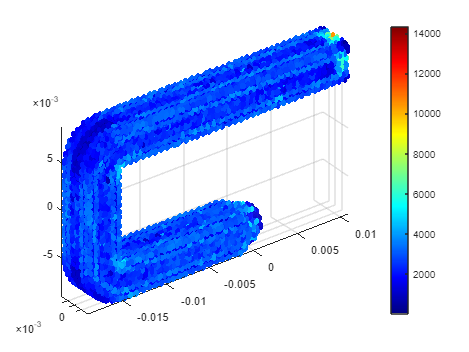

easyvisualizer.plotFillElementData(elementcoordinates, elementfillstatus, sheardiffs, timestep, 'no')

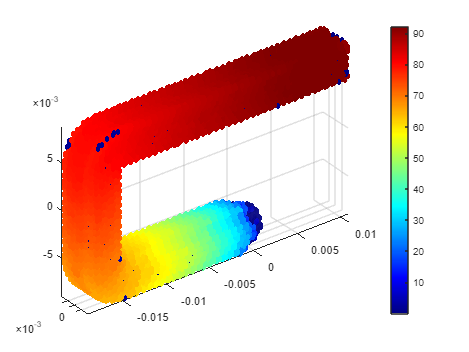

easyvisualizer.plotFillElementData(elementcoordinates, elementfillstatus, tempdiffs, timestep, 'no')

% Calculating highdiffelements by shear diffs
[highsheardiffs_t2, normalsheardiffs_t2, highsheardiffsbytimestep_t2] = meshrefiner.calcHighDiffElements(elementfillstatus, sheardiffs, 1.25, true);
[highsheardiffs_t25, normalsheardiffs_t25, highsheardiffsbytimestep_t25] = meshrefiner.calcHighDiffElements(elementfillstatus, sheardiffs, 1.5, true);
[highsheardiffs_t3, normalsheardiffs_t3, highsheardiffsbytimestep_t3] = meshrefiner.calcHighDiffElements(elementfillstatus, sheardiffs, 2, true);

% Calculating highdiffelements by temperature diffs
[hightempdiffs_t2, normaltempdiffs_t2, hightempdiffsbytimestep_t2] = meshrefiner.calcHighDiffElements(elementfillstatus, tempdiffs, 2, true);
[hightempdiffs_t25, normaltempdiffs_t25, hightempdiffsbytimestep_t25] = meshrefiner.calcHighDiffElements(elementfillstatus, tempdiffs, 2.5, true);
[hightempdiffs_t3, normaltempdiffs_t3, hightempdiffsbytimestep_t3] = meshrefiner.calcHighDiffElements(elementfillstatus, tempdiffs, 3, true);

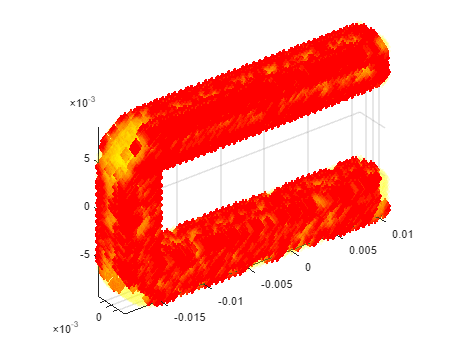

% Visualizing highsheardiffelements
easyvisualizer.plotElementsToRefine(elementcoordinates, highsheardiffs_t2, normalsheardiffs_t2, 0)

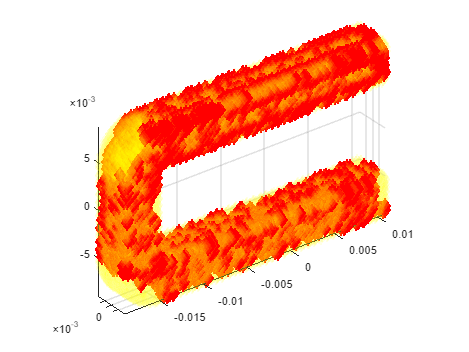

easyvisualizer.plotElementsToRefine(elementcoordinates, highsheardiffs_t25, normalsheardiffs_t25, 0)

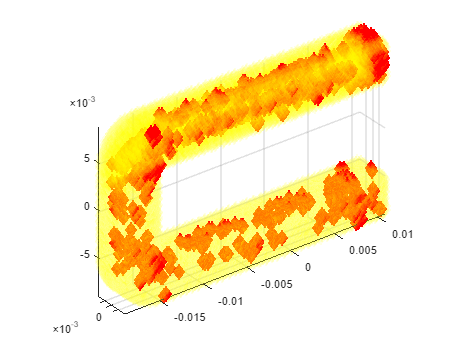

easyvisualizer.plotElementsToRefine(elementcoordinates, highsheardiffs_t3, normalsheardiffs_t3, 0)

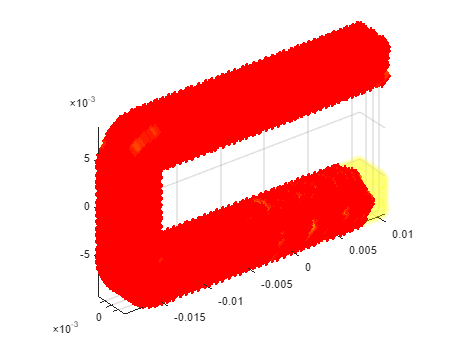


% Visualizing hightempdiffelements
easyvisualizer.plotElementsToRefine(elementcoordinates, hightempdiffs_t2, normaltempdiffs_t2, 0)

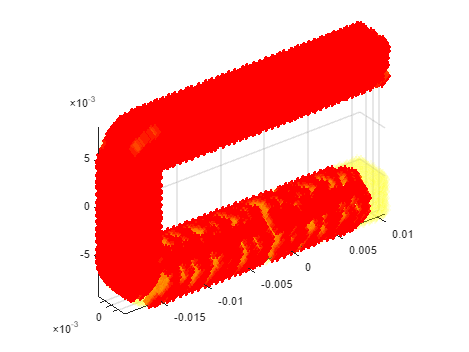

easyvisualizer.plotElementsToRefine(elementcoordinates, hightempdiffs_t25, normaltempdiffs_t25, 0)

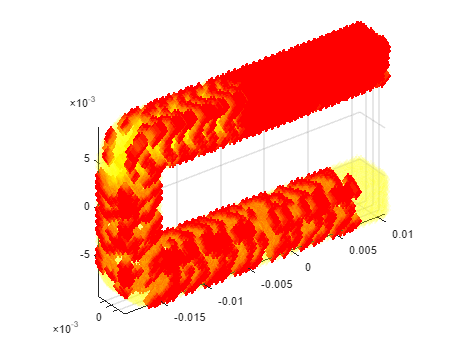

easyvisualizer.plotElementsToRefine(elementcoordinates, hightempdiffs_t3, normaltempdiffs_t3, 0)

tic
[newnodepos, newelementnodeids, affectedelements] = meshrefiner.createNewMeshMultiNode(nodepos, elementnodeids, highsheardiffs_t25);
udmwriter.createUDM(newnodepos, newelementnodeids, 'outputs/multi_shear_t2.udm');
toc

Elapsed time is 84.553384 seconds.


unique(highsheardiffs_t2(:, 1))

ans =      2
     3
     4
     5
     6
     7
     8
     9
    10
    11


tic
[newnodepos, newelementnodeids] = meshrefiner.createNewMeshOneNode(highsheardiffs_t25, shearrates, elementnodeids, nodepos, false);

newnodes =     0.0109    0.0002    0.0065
    0.0107   -0.0000    0.0067
    0.0109   -0.0002    0.0068
    0.0108   -0.0003    0.0071
    0.0107    0.0003    0.0073
    0.0106    0.0002    0.0071
    0.0109    0.0002    0.0074
    0.0106    0.0002    0.0068
    0.0106   -0.0001    0.0072
    0.0108   -0.0000    0.0074


newnodeids =            1           2           3           4        7231
           1           2           5           3        7232
           3           5           1           6        7233
           6           5           1           7        7234
          10           9          11           1        7235
           5          11           9           1        7236
          10          11           8           1        7237
           1           5           2           9        7238
           5          11           1           7        7239
           1          11           8           7        7240


newnodeconnections =            1           2           3        7231
           1           2           4        7231
           1           3           4        7231
           2           3           4        7231
           1           2           5        7232
           1           2           3        7232
           1           5           3        7232
           2           5           3        7232
           3           5           1        7233
           3           5           6        7233


newelementnodeids =      1     2     3     4
     1     2     5     3
     3     5     1     6
     8     7     6     1
     6     5     1     7
    10     9    11     1
     5    11     9     1
    10    11     8     1
     1     5     2     9
     5    11     1     7


newelementnodeids =     17    13     2    16
     2    15    16     9
    16    13     2     9
     5    15    18     2
     2    17     4    13
     2    15     9     5
    30     5    15    28
    30     5    28     7
    30     5    11    15
     5    15    28    18


udmwriter.createUDM(newnodepos, newelementnodeids, 'outputs/one_shear_t2.udm');
toc

Elapsed time is 11.103393 seconds.
